# **Task_01a:**  Explore an Impact test on a  3-floor-tower with **Stationary** Ground 

Let's explore a 3-floor-tower with a **Stationary ground** ... and apply a **horizontal (**$X-\mathrm{dir}$**) impact force** to the **1st floor.**

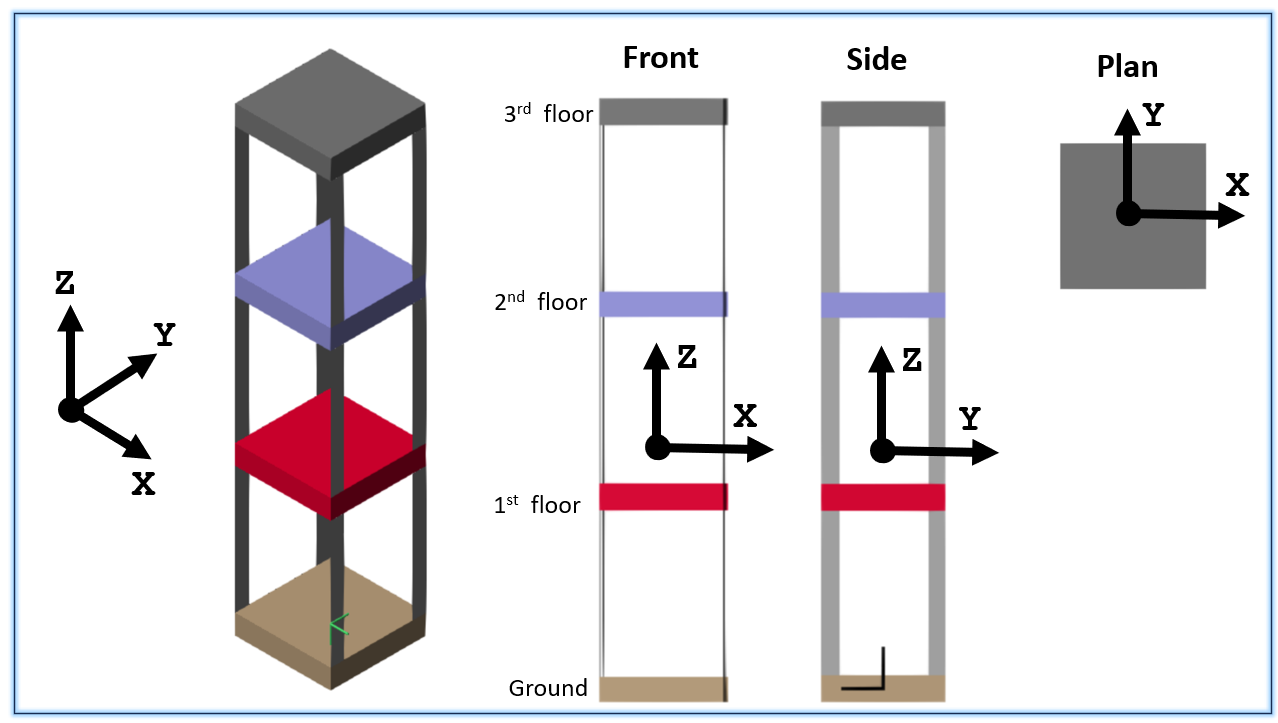

Some typical **horizontal (**$X-\mathrm{dir}$**) **excitation **forces** and **responses** (timeseries) are shown below:

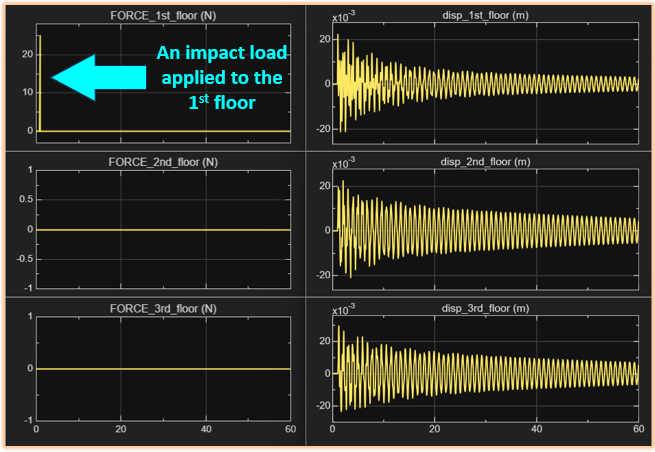

## Clear the workspace

clear

## Consult Parameter database

Consult database for parameters :

- See:   [`bh_flex_tower_params_CLS.m`](matlab:  open  bh_flex_tower_params_CLS.m)

- See:   [`bh_flex_tower_params_database.xlsx`](matlab:  winopen bh_flex_tower_params_database.xlsx)

params_dB = bh_flex_tower_params_CLS("bh_flex_tower_params_database.xlsx", "DEFAULT");

## Define the columns

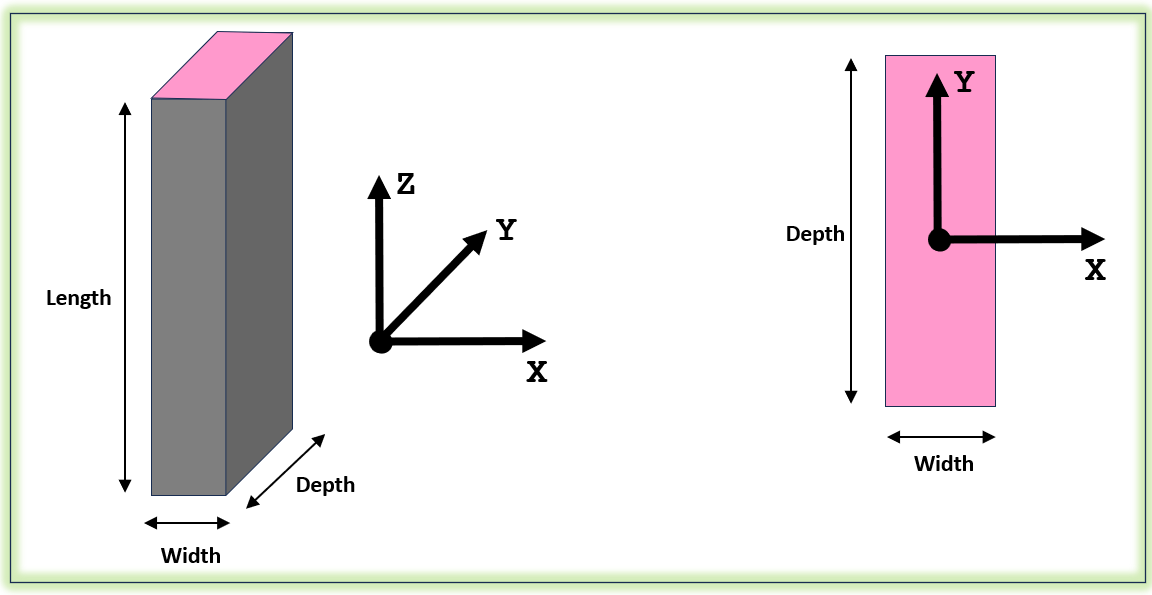

col_OBJ  = bh_create_column_OBJ( Width=params_dB.col_width_x, ...
                                 Depth=params_dB.col_depth_y, ...
                                 Length=params_dB.col_length_z, ...
                                 density=params_dB.col_density, ...
                                 E_GPa_Young=params_dB.col_E_Gpa, ...
                                 v_Poisson=params_dB.col_Poisson);

col_OBJ.num_eles      = params_dB.col_num_eles;
% col_OBJ.num_eles      = 3;

Define column damping

col_OBJ.damp_ratio = params_dB.col_damp_ratio;

So what've we got

col_OBJ

col_OBJ =   bh_flex_column_CLS with properties:

          WIDTH_x: 3.5000e-04
          DEPTH_y: 0.0170
         LENGTH_z: 0.1600
          density: 7900
      E_GPa_Young: 170
        v_Poisson: 0.3000
     damp_M_coeff: 0
     damp_K_coeff: 1.0000e-03
       damp_ratio: 0.0500
         num_eles: 1
    num_ret_modes: 5
          BC_case: "FIXED_FIXED_WITH_SWAY"
             mass: 0.0075
              vol: 9.5200e-07
               Ix: 1.4330e-10
               Iy: 6.0740e-14
               Kx: 30.2512
             area: 5.9500e-06


## Define the floors

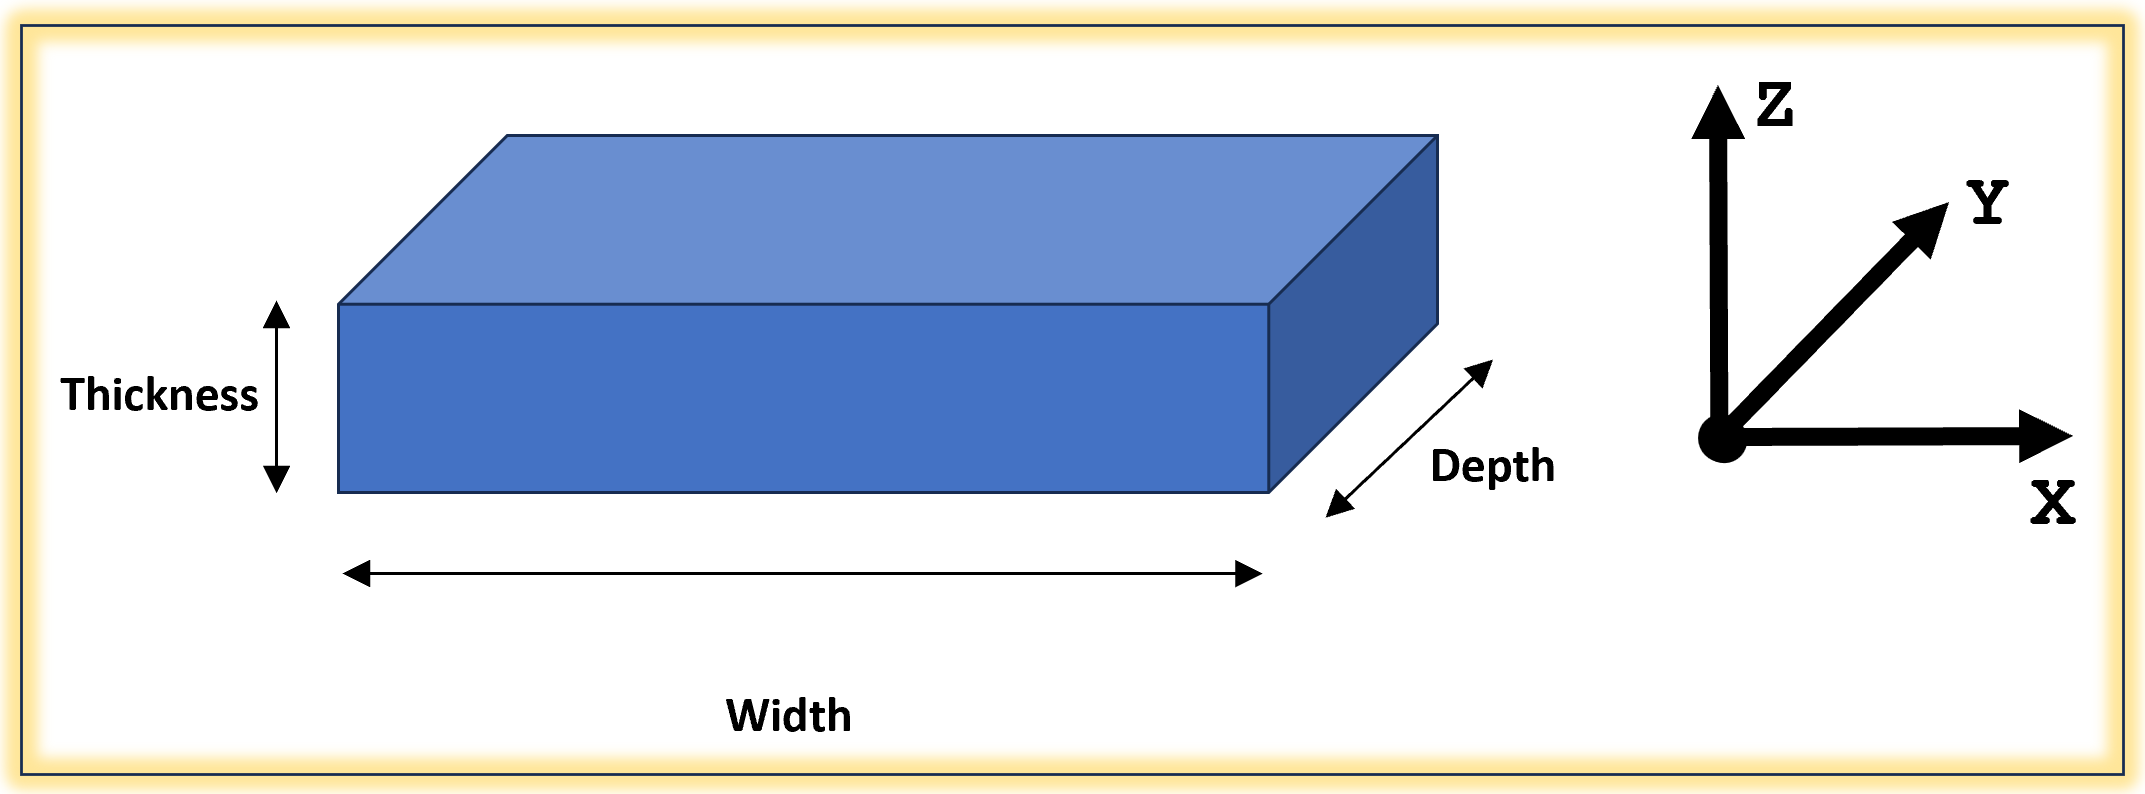

floor_OBJ = bh_create_floor_OBJ( Width=params_dB.floor_width_x, ...
                                 Depth=params_dB.floor_depth_y, ...
                                 Thickness=params_dB.floor_thick_z, ...
                                 Mass=params_dB.floor_mass )

floor_OBJ =   bh_solid_floor_CLS with properties:

        WIDTH: 0.1200
        DEPTH: 0.1200
    THICKNESS: 0.0250
         MASS: 0.5080


## Magnitude of Impact Load

F_applied = 25; % (N)

## Define parameters for the checkered looking Earth ground

earth_vis_OBJ = earth_vis_CLS();
earth_vis_OBJ.tile_L = 0.1;  % (m)

## Open and RUN the Simulink model

open_system("bh_3floor_tower_STATIONARY_GROUND_impact_test.slx")

When the Simulink model finishes it's simulation, an EXCEL file named `bh_IMPACT_TEST.xlsx` is created.  

-  You should rename this EXCEL file to some sensible name - we'll analyze this RENAMED file in the next task - [`TASK_01b_3floor_tower_do_sys_ID.mlx`](matlab:  open  TASK_01b_3floor_tower_do_sys_ID.mlx)